# Create Building Model With Solar Load

Copyright 2024 The MathWorks, Inc.

This project shows how to define a building's floor plan by starting with the layout and definition of individual rooms. In this project, a building consists of multiple apartments, each containing various rooms such as a living room, kitchen, bathroom, and bedroom. A single building can contain several apartments. The orientation of the floor plan of an apartment must be defined in reference with global directions: North (N), East (E), South (S), and West (W). The project uses specific convention to indicate directions on a 2D plot. This workflow guides you through orienting your floor plan in the desired direction and adding windows and vents to the external walls.

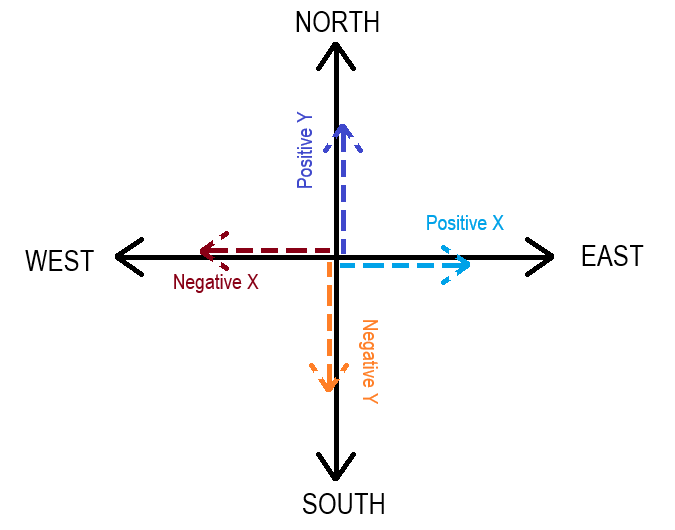

Once your floor plan is prepared, you will construct a 3D building by extending the floor plan in the z-direction, or the vertical axis. All of the windows and vents on a particular wall are uniform in size across the different floor levels. This process is illustrated in the diagram below and described in detail in the following sections.

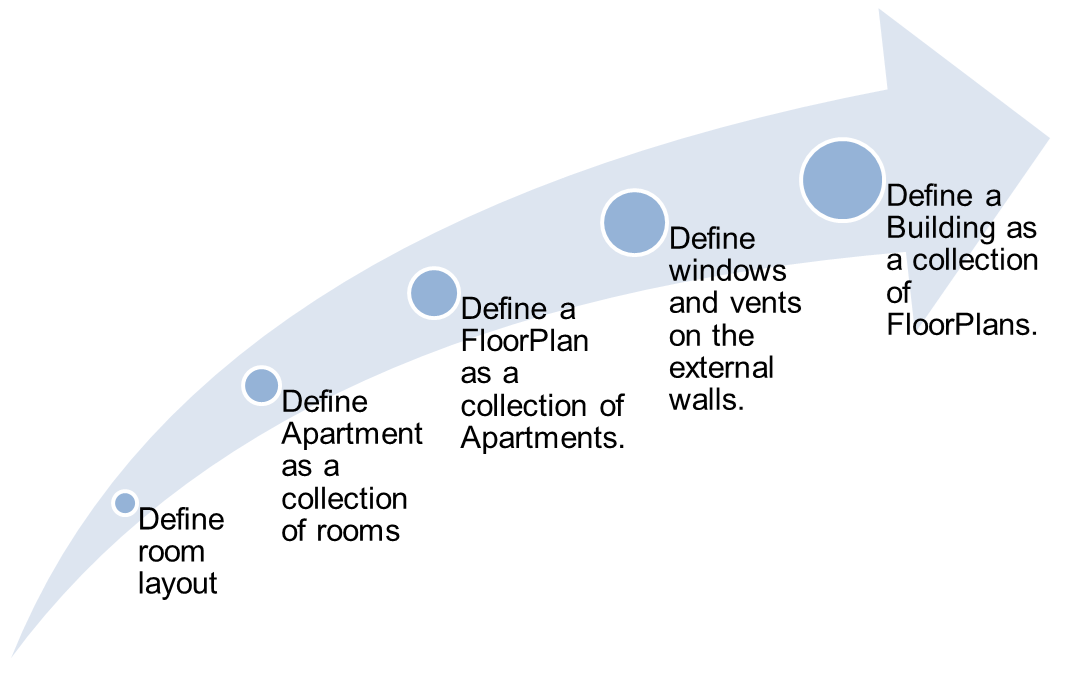

## Create Building

### Design Floor Plan

Use the function `addRoomToFloorPlan()` to add the room to the apartment unit. See [Function Reference List](matlab:open('../Overview/html/FunctionReferenceList.html')) for more details on the function.

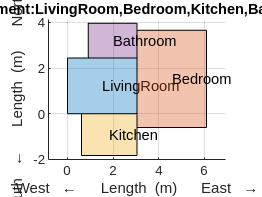

% Initialize a data struct for one apartment unit.
oneAptUnit  = []; 

% Living Room
oneAptUnit   = addRoomToFloorPlan(FloorPlan=oneAptUnit,...
                                  NewRoom="LivingRoom",...
                                  Vertex=simscape.Value([0,0],'ft'),...
                                  Length=simscape.Value(8,'ft'),...
                                  Width=simscape.Value(10,'ft'),...
                                  Angle=simscape.Value(0,'deg'));

% Bedroom
oneAptUnit   = addRoomToFloorPlan(FloorPlan=oneAptUnit,...
                                  NewRoom="Bedroom",...
                                  Vertex=simscape.Value([10,-2],'ft'),...
                                  Length=simscape.Value(14,'ft'),...
                                  Width=simscape.Value(10,'ft'),...
                                  Angle=simscape.Value(0,'deg'));
% Kitchen
oneAptUnit   = addRoomToFloorPlan(FloorPlan=oneAptUnit,...
                                  NewRoom="Kitchen",...
                                  Vertex=simscape.Value([2,-6],'ft'),...
                                  Length=simscape.Value(6,'ft'),...
                                  Width=simscape.Value(8,'ft'),...
                                  Angle=simscape.Value(0,'deg'));
% Bathroom
oneAptUnit   = addRoomToFloorPlan(FloorPlan=oneAptUnit,...
                                  NewRoom="Bathroom",...
                                  Vertex=simscape.Value([3,8],'ft'),...
                                  Length=simscape.Value(5,'ft'),...
                                  Width=simscape.Value(7,'ft'),...
                                  Angle=simscape.Value(0,'deg'),...
                                  Plot=true);

Define one apartment unit.

modelApt = defineSingleApartmentUnit(Apartment=oneAptUnit,...
                                     Tol=0.01);

clear room oneAptUnit

### Define Floorplan Orientation

You can use the `copyMoveRotateForNewApartment` function to duplicate the apartment by either moving it a specified distance or rotating it. The following code keeps the apartment stationary but rotates it by 15 degrees around *Bedroom*'s vertex.

apartment  = copyMoveRotateForNewApartment(Apartment=modelApt,...
                                           MoveDistance=simscape.Value([0,0],'ft'),...
                                           RotationAngle=simscape.Value(15,'deg'),...
                                           RotateAboutRoom="Bedroom",...
                                           Tol=0.01);

Define the floor plan by consolidating all apartment definitions into a single cell array. The following code defines the floorplan using just one apartment.

floorPlan = defineBuildingFloorPlan(Apartments={apartment});

Plot and visualize the floorplan.

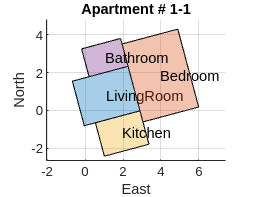

figure('Name','Floor Plan Consolidated');
plotFloorPlanLayout(PlotData=floorPlan,Type="floorplan")

### Define Windows, Vents

Visualize all the external walls and their identification numbers.

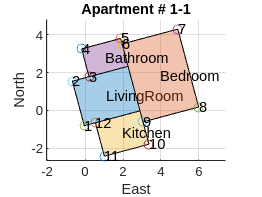

Use function addOpeningOnWallSection() to add windows or vent to the walls.


visualizeBuildingWallsToAddWindowsVents(FloorPlan=floorPlan);

Add windows to a specified set of wall sections. Each row entry below represents a unique wall specification. The first two columns define the wall section indices, while the third column indicates the fraction of the total wall area covered by windows or vents. In this example, walls represented by indices 1-2, 4-5, 7-8, 8-9, and 10-11 have windows with areas specified as 70%, 30%, 70%, 50%, and 70% of the respective wall area.

windowData = [1,2,0.7; ...
              4,5,0.3; ...
              7,8,0.7; ...
              8,9,0.5; ...
              10,11,0.7];
updatedFloorPlan = addOpeningOnWallSection(FloorPlan=floorPlan,...
                                           Data=windowData,...
                                           Type="window");

### Define Multi-Storied Building

Set angle to view all 3D plots.

viewingAngle = [-1 -1 1]; 

Generate building 3D model with 3 levels and each level height.

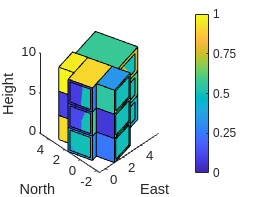

building = generateBuilding3Dlayout(BuildingName="BuildingUnit",...
                                    BuildingFloorPlan=updatedFloorPlan,...
                                    NumberOfLevels=3,...
                                    LevelHeight=simscape.Value(10,'ft'),...
                                    Tol=0.01);
figure('Name','BuildingUnit Elevation');
plot3DlayoutBuilding(Building=building,...
                     PlotViewDirection=viewingAngle,...
                     ColorScheme="random");

## Define Solar Load on Building

Define the building geographical location. If your location is not included in the list of cities, create a `geoLocation` template and add the necessary data. For more information, see the documentation for function `getGeoLocationForMajorCities` in the [Function Reference List](matlab:open('../Overview/html/FunctionReferenceList.html')).

geoLocation = getGeoLocationForMajorCities(CityName="Bengaluru");

Specify the datetime duration.

tStart = datetime(2024,5,1,1,0,0); % YYYY,MM,DD,HR,MM,SS
tEnd   = datetime(2024,5,7,1,0,0); % YYYY,MM,DD,HR,MM,SS

Update the building 3D model with solar radiation data on the walls and roof.

apartment3D = getHourlyBuildingSolarLoad(Building=building,...
                                         Location=geoLocation,...
                                         DayLightSavingHrs=0,...
                                         StartTime=tStart,...
                                         EndTime=tEnd);

### Visualize Solar Loading

showPlotForSolarLoad = false;

You can plot solar data, the sunlight falling on building walls and roof, by setting parameter showPlotForSolarLoad to `Display Plot`, in the drop down list.

if showPlotForSolarLoad
    dateTimeVec = tStart:hours(1):tEnd;
    for nHrs = 1:length(dateTimeVec)
        figure('Name',strcat('BuildingPlotNum',num2str(nHrs)));
        plot3DlayoutBuilding(Building=apartment3D,...
                             PlotViewDirection=viewingAngle,...
                             ColorScheme="sunlight",...
                             Hour=nHrs);
        title(strcat(geoLocation.Row,', Date/Time :',string(dateTimeVec(1,nHrs))));
    end
end

## Save Building Data

Save the building data with solar radiation load, specified for a given datetime duration, in an XML file. You can load this part file later and use it for analysis.

writeBuildingDataXML(Location=geoLocation,...
                     StartTime=tStart,...
                     EndTime=tEnd,...
                     Building=apartment3D,...
                     FileName='building_with_solar_load.xml');